# Учебный файл 

## Студента: Красницкого Никиты

Задание массивов, столбцов, строк

а - строка. b - столбец. c - матрица 3х3, zс - столбец нулей, zr - строка нулей, om - матрица единиц, далее достаточно комментариев

- Индексация матриц начинается с 1, а не с 0

clear all % Очистка памяти от переменных (очистка Workspace)
close all % Закрытие всех окон, открытых программно
clc       % Очищает историю коммандной строки
a = [1 2 3 4 5]
b = [4 5 6 7 8]' % Операция транспонировки
c = [1 2 3; 4 5 6; 7 8 9]
zc = zeros(3, 1)
zr = zeros(1, 3)
om = ones(3, 3)
c = c.*om% Перемножение одинаковых элементов матриц 
cc = c.*c
cmc = c*c % Перемножеие матриц
c3 = c.^3 % Возведение в куб каждого элемента матрицы
RowC3 = [c, c, c]
ColC3 = [c; c; c]
ComplexMatrix = [1+2i, 5 - 3i; 1j, 8 + 1j]
ComplexMatrix3 = ComplexMatrix(3)    % Все элементы идут подряд считая по столбцам. 
                                     % Последний эл первого столбца->первый эл второго столбца..
ComplexMatrix3 = ComplexMatrix(1, 2) % Строка, Столбец

## Еще о массивах. Вывод данных, их сохранение

clear all
close all
clc
A = 0:7:35 % Start : Step : End
A = [A; A]
B = A(1,:) % Первая строка и каждый столбец
C = A(:,2) % Второй столбец и каждая строка
whos       % Показывает какие есть переменные в памяти и всю информацию о них
V = rand(2, 3 ,4) % Многомерная матрица. 2 строки, 3 столбца, 4 матрицы размером 2х3
%rand(F)    создает матрицу FхF и заполняет случайными числами от 0 до 1
%rand(F,2)  создает матрицу Fx2 (F строк и 2 столбца)
%randi(100) случайное число от 0 до 100
b = rand(1)
save myfilesdata.mat % Сохраняет все переменные в файл myfilesdata.mat.
                     % Двойным кликом дата восстановится
b = 43
load myfilesdata.mat % Загружаем сохраненную ранее дату. 
                     % b должно снова иметь значение от 0 до 1
                     
[maxA,location] = max(V(:,:,1)) % Находим максимумы в колонках первой матрицы V
                                % И их позиционирование. 1 - первый, 2 - второй элемент
disp('hello world'); % Вывод данных в виде строки

## График простой

x = 0:pi/100:2*pi % Строка из 200 чисел с 0 до 2*pi
y = sin(x);       % Строка из 200 синусов, взятых от чисел выше
plot(x, y)        % Независимая переменная, функция

## График замороченый

clear all
close all
clc
x = 0:pi/100:2*pi;
y = sin(x);      
plot(x, y)
xlabel('Независимая переменная x')
ylabel('sin(x)')
title('Plot of the sine function')

hold on % Пока нет hold off - все графики будут рисоваться в одном окне (друг на друге)

y2 = cos(x);
plot(x,y2,':') % Выводить график символами - точками

y3 = log(x + 0.001);
plot(x,y3,'g--') % Выводить график символами - штрихом
axis([0, 2*pi, -1.5, 1.5]); % Функция требует строку, в которой первые два чила - границы Х
                            % Вторые два чила - границы Y

legend('sin','cos', 'log')

hold off

## Циклы и условные операторы

clear all
close all
clc
N = 100;
f(1) = 1;
f(2) = 1;
f
f(3) = 2; % Пример динамичности данных в MatLAB
f
for n = 4:N
    f(n) = f(n-1) + f(n-2);
end
f(1:10) % Вывести первые 10 чисел Фибоначчи

num = randi(100); % случайное число от 0 до 100
if num <= 34
   sz = 'low';
elseif num >= 67
   sz = 'medium';
else
   sz = 'high';
end
disp(['Size of the number is ', sz])

## Функции и их спектры

Когда происходит преобразование фурье, в данном случае дискретное быстрое преобразование, встроенные фкункции матлаба возвращают столбец значений, который начинается с положительных частот, в середине этого столбца, сразу после максимальной положительной частотой находится нулевая частота (середина спектра), а заканчивает он отрицательными частотами, которые подходят до нуля. Это можно увидеть на графике модуля спектра (АЧХ, abs(S)) и проследить в коде как потом этот столбец разбивают на два и получают привычный вид спектра только положительных частот (P1)

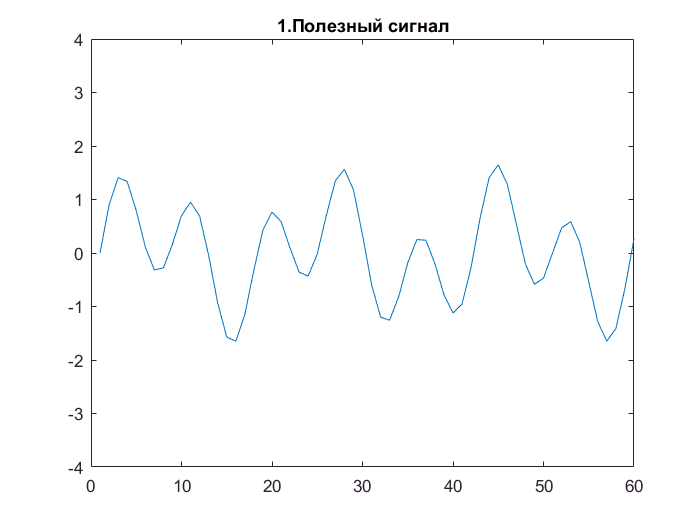

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector
f = Fs*(0:(L/2))/L;   % Приводим единицы абсцисс к Герцам

S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);  % Сигнал - сумма двух сигналов
plot(S)
axis([0 60 -4 4]) % Увеличим оси, что бы посмотреть на график. 
                   % На самом деле пределы Х 0-1500

title('1.Полезный сигнал')

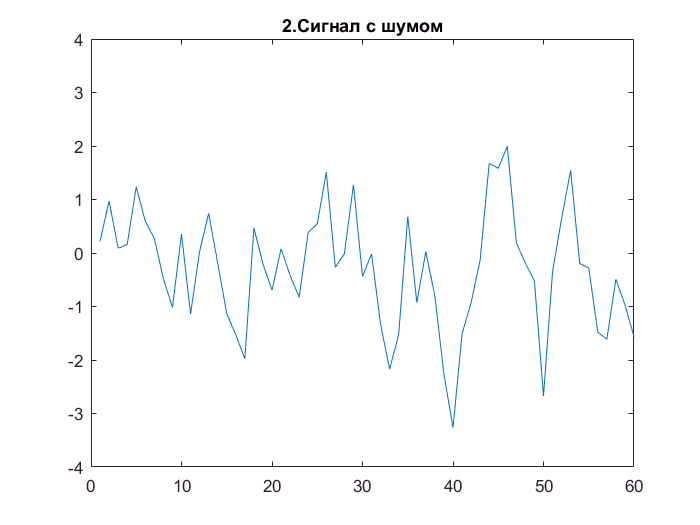

R = 1*randn(size(t));
X = S + R; % Сигнал с шумом
plot(X)
axis([0 60 -4 4])
title('2.Сигнал с шумом')

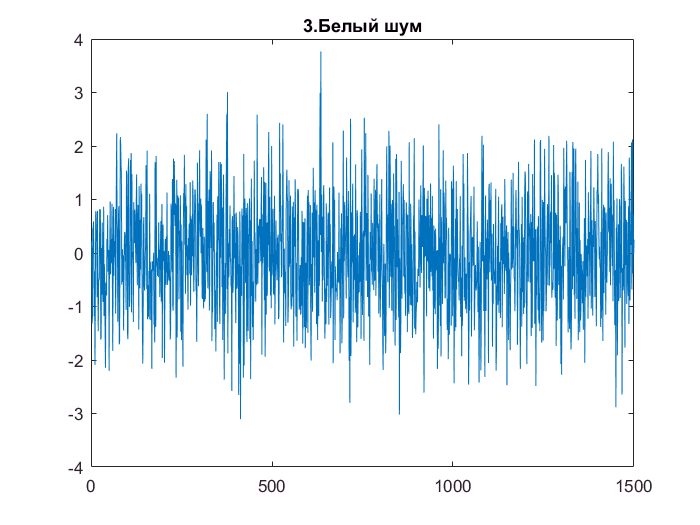

plot(R)  % Белый шум (мат модель)    
title('3.Белый шум')  

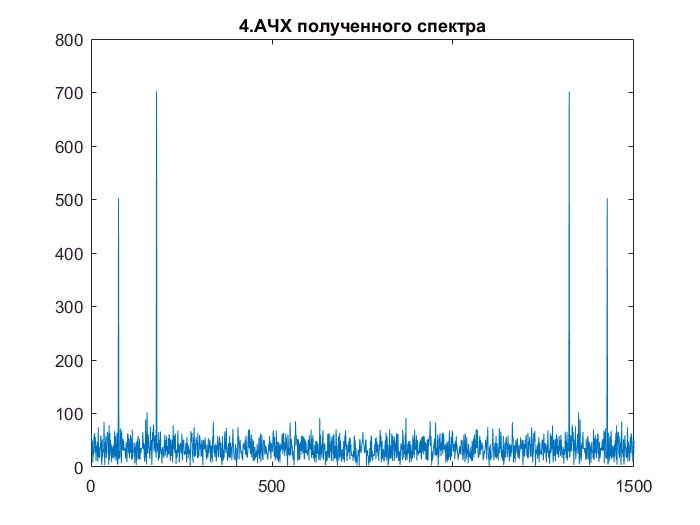


Sp = fft(X); % Дискретное Быстрое Преобразование Фурье от зашумленного сигнала 
plot(abs(Sp));
title('4.АЧХ полученного спектра') 

P2 = abs(Sp/L);
P2c = Sp/L;            % Complex P2
P1c = P2c(1:L/2 + 1); % Complex P1
P1c(2:end-1) = 2*P1c(2:end-1);
P1 = P2(1:L/2 + 1);          % Берем только первую половину спектра ( положительные частоты )
P1(2:end-1) = 2*P1(2:end-1); % Увеличиваем ее вдвое, т.к. раньше она была и в отр. частотах
line = 1*ones(1, L/2+1);
line2 = 0.7*ones(1, L/2+1);
%hold off % Не изображаем графики, рисовавшиеся до этого момента
figure   % Без этой строки график АЧХ накладывается ниже. Почему - ВОПРОС

figure =     NextPlot: 'new'


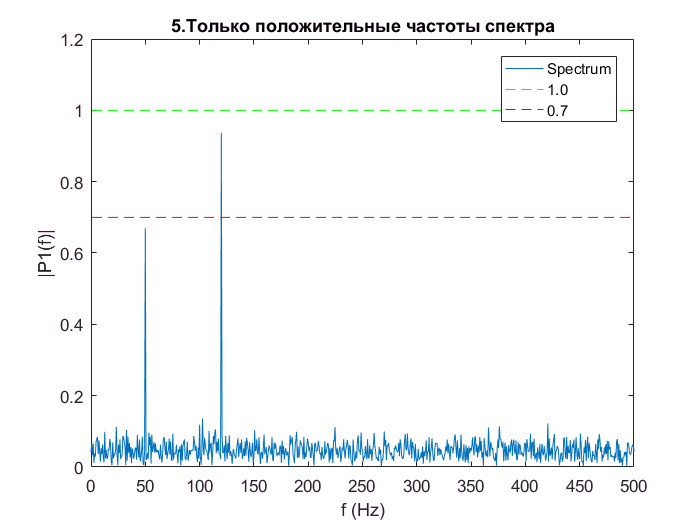

plot(f, P1);
hold on % Изображаем следующие графики вместе c P1
plot(line, 'g--')
plot(line2, 'r--')
title('5.Только положительные частоты спектра')
legend('Spectrum','1.0', '0.7')
xlabel('f (Hz)')
ylabel('|P1(f)|')
axis([0 max(f) 0 1.2])
hold off


% Для восстановления сигнала используем комплексный спектр P1c, а не его АЧХ P1
% Фильтрация за уровнем. Работает, если соотношение сигнал / шум достаточно большое.
figure.NextPlot = 'new';
e = 0.175

e = 0.1750

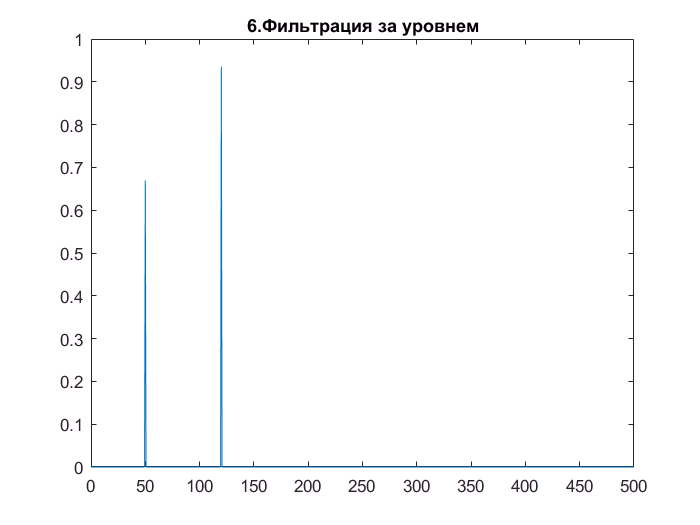

for i = 1:numel(P1c)
    if abs(P1c(i)) < abs((max(P1c)))*e
        P1c(i) = 0;
    end
end
plot(f, abs(P1c))
title('6.Фильтрация за уровнем')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% КОСТЫЛЬ. Нужен вариант лучше!
Sp = P1c(1:L/2 + 1); % 1 -- 751
for i = (L/2+2):L-1 % 752 -- 1499
    Sp(i+1) = P1c(L+1 - i); %  Plc( 1501 - i ) Идет от 749 до 2 = Костыль для симметрии значений
end
if abs(Sp(76)) == abs(Sp(L-74)) && abs(Sp(181)) == abs(Sp(L-179))
    disp('Восстановленный спектр симметричный!')
else
    disp('Восстановленный спектр не симметричный!')
end

Восстановленный спектр симметричный!


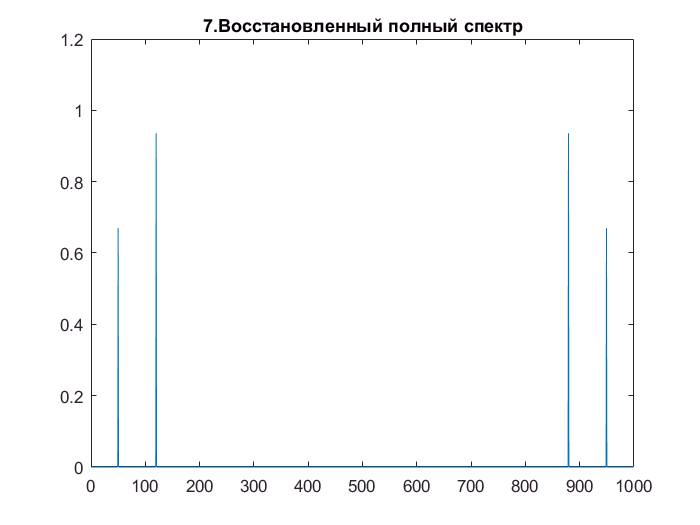

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
F = [f (f+500)]; % Вдвое увеличенный диапазон частоты f
plot(F(1: end-2), abs(Sp))
title('7.Восстановленный полный спектр')
axis([0 max(F) 0 1.2])

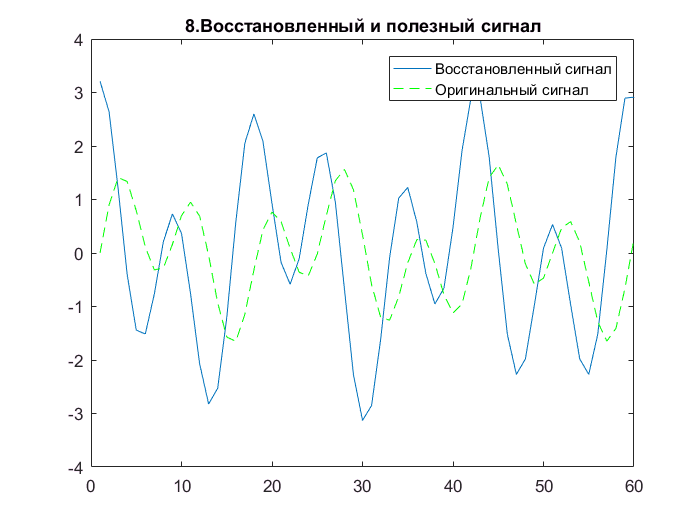

Y = ifft(abs(Sp)) * L; %%%%%%%%%%%%%%%%%%% В ОПФ должен идти комплекный спектр, а не АЧХ
                       %%%%%%%%%%%%%%%%%%% Это очередной костыл, где теряется фаза сигнала
figure;
plot(Y)
hold on
plot(S, 'g--')
axis([0 60 -4 4])
title('8.Восстановленный и полезный сигнал')
legend('Восстановленный сигнал','Оригинальный сигнал')
hold off

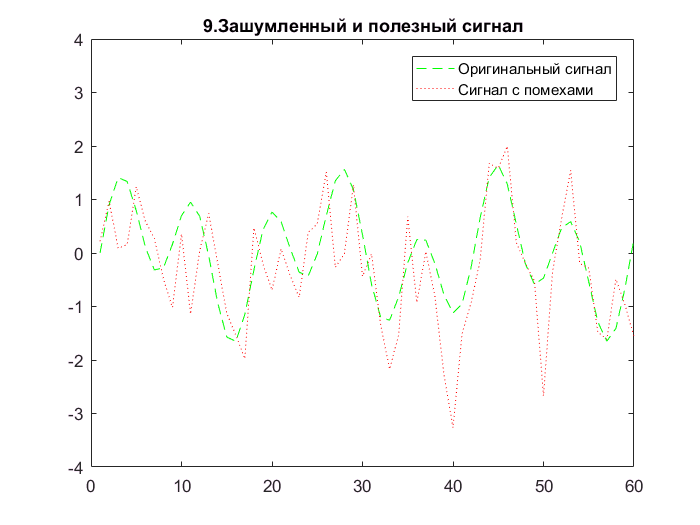


figure;
plot(S, 'g--')
hold on
plot(X, 'r:')
axis([0 60 -4 4])
title('9.Зашумленный и полезный сигнал')
legend('Оригинальный сигнал', 'Сигнал с помехами')
hold off